**Generación de la linea de código para el micrcontrolador - **vector de coeficientes

Copiar y pegar en el STM32/ARDUINO. Ejemplo.

                                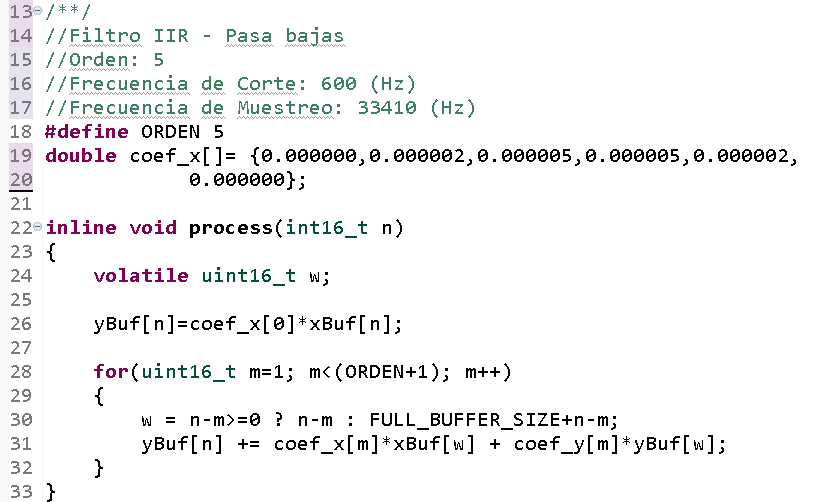

function [salida]=to_stm32(Bz, Az, N, Fm, PRECISION, TIPO ,MAPEO)

    if(nargin<7)
        MAPEO="";
    end

    ORDEN=max([N, length(Bz), length(Az)]);
    ORDEN=ORDEN;

    linea_x='double coef_x[]= { ';
    for m=1:ORDEN
        if(m<=length(Bz))
            linea_x=strcat( linea_x, num2str(Bz(m), strcat('%.',num2str(PRECISION), 'f'))  );        
        else
            linea_x=strcat( linea_x, num2str(0, strcat('%.',num2str(PRECISION), 'f'))  );        
        end
        
        if m<ORDEN
            linea_x=strcat( linea_x,',') ;       
        end
    
        if mod(m,5 )==0
            linea_x=sprintf("%s \n\t\t\t",linea_x );
        end
    end
    linea_x=strcat(linea_x,'};') ; 
    
    linea_y='double coef_y[]= { ';
    for m=1:ORDEN
        
        if(m<=length(Az))
            linea_y=strcat( linea_y, num2str(-Az(m), strcat('%.',num2str(PRECISION), 'f'))  );        
        else
            linea_y=strcat( linea_y, num2str(0, strcat('%.',num2str(PRECISION), 'f'))  );        
        end

        if m<ORDEN
            linea_y=strcat( linea_y,',') ;       
        end
    
        if mod(m,5 )==0
            linea_y=sprintf("%s \n\t\t\t" ,linea_y);
        end
    end
    linea_y=strcat(linea_y,'};') ; 
    
   

    salida=sprintf('//Filtro %s - %s \n//Orden: %d\n//Frecuencia de Muestreo: %d (Hz)\n#define ORDEN %d\n%s\n%s', ...
             TIPO, MAPEO, N,Fm, ORDEN-1, linea_x, linea_y);    
end